cd(fileparts(matlab.desktop.editor.getActiveFilename));

tbl = readtable("dati/tcurve.txt", NumHeaderLines=3);
tbl.Properties.VariableNames = ["freq", "abs", "phase"];

% converto in modulo lineare
tbl.abs = 10.^(tbl.abs/20);

% valori iniziali componenti
R1 = 99.9e3;
C1 = 100e-9;
R2 = 994;
C2 = 47e-9;

t1 = R1*C1;
t2 = R2*C2;

% p(1)=tau1, p(2)=tau2, p(3)=R1, p(4)=C2
% guess iniziale
p0 = [t1, t2, R1, C2];


H = @(p,f) (1j*2*pi*f.*p(1)) ./ ...
           ( (1 + 1j*2*pi*f.*p(1)) .* (1 + 1j*2*pi*f.*p(2)) + 1j*2*pi*f.*p(3).*p(4) );

G = @(p,f) abs(H(p,f))

G = function_handle with value:
    @(p,f)abs(H(p,f))


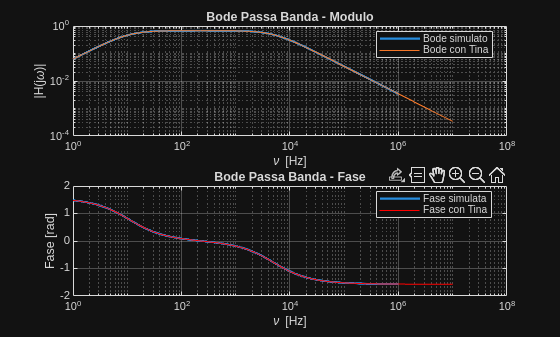


% frequenze logaritmiche da 1 Hz a 1e6 Hz
x = logspace(0, 6, 10000);

% valutazione della funzione con parametri ottimizzati
y = H( p0,x);

figure

% --- Subplot 1: modulo ---
subplot(2,1,1)
loglog(x, abs(y), 'LineWidth', 1.8)
hold on
loglog(tbl.freq, tbl.abs)
% loglog(tbldatax.freq, tbldata.abs, 'o')
hold off
legend("Bode simulato", "Bode con Tina", 'Location', 'best')
xlabel('\nu [Hz]')
ylabel('|H(j\omega)|')
title('Bode Passa Banda - Modulo')
grid on

% --- Subplot 2: fase ---
subplot(2,1,2)
semilogx(x, angle(y), 'LineWidth', 1.8)
hold on
plot(tbl.freq, tbl.phase*pi/180, "r")
hold off
xlabel('\nu [Hz]')
ylabel('Fase [rad]')
legend("Fase simulata", "Fase con Tina", 'Location', 'best')
title('Bode Passa Banda - Fase')
grid on

% --- Esporta la figura ---
exportgraphics(gcf, "grafici/Simulazioni_CRRC.pdf", ContentType = "vector");


% guadagni a frequenze specifiche
ff = [10, 1e2, 1e3, 1e4];
GG = abs(H(ff, popt))

GG = 1.0e-06 *

    1.0000    1.0000    0.0165    0.9431
